clc;clear;close all;

## 1、生成点

% warning off
% 
% x = [-0.17263699	0.64102824	0.619187272	-0.169604585	-0.172290695	0.640753956	0.621242344	-0.170769907	-0.171522965	0.640246152	0.624506602	-0.171830944	-0.17083717	0.639008371	0.628110178	-0.171314854];
% y = [0.018979904	0.142571117	0.609214188	0.276047528	-0.053249894	-0.032656584	0.438329502	0.208959385	-0.125595109	-0.206542736	0.267949915	0.140160375	-0.198118165	-0.378594402	0.096932468	0.069163785];
% z = [-0.344388792	-0.670489171	0.286631526	0.1830114	-0.309268295	-0.580626074	0.372157833	0.220360057	-0.273244453	-0.491250982	0.458562455	0.258402244	-0.237311062	-0.402116506	0.545590665	0.294559421];
% 
% 
% azimuth = 5.819341;
% elevation = 1.582673;
% 
% P1 = [-0.25222006 0.655135248 -0.327650295];
% P2 = [-0.249753513 -0.390018781 0.195244076];
% 
% % xx = [-0.166541824	-0.143183482	0.086083038	0.156469149	0.466618822	0.56448817	0.839716947	0.807804096];
% % yy = [-0.049231542	0.233661612	-0.104236007	0.34170614	-0.091332629	0.380144412	0.261440943	0.017627278];
% % zz = [0.365326614	-0.524532874	0.659289339	-0.829545167	0.707237057	-0.813472591	-0.522760129	0.428110448];
% % PointFC = [xx;yy;zz];
% Points = [x;y;z];
% % Points = [Points,PointFC];
% 
% PAB = Points(:,5);



## 1、读取点

warning off
[num,txt,raw] = xlsread("2024_12_13.xlsx");
num(4:5,:)=[];

% num = [num(1:15,:);num(13:17,:);num(16:end,:)];
x = num(27,~isnan(num(27,:)));
y = num(29,~isnan(num(29,:)));
z = num(28,~isnan(num(28,:)));
azimuth = num(24,1);
elevation = num(24,2);
Points = [x;y;z];

PAB = num([19,21,20],2);
% PAB = Points(:,5);


P1 = num([50,52,51],2);
P2 = num([50,52,51],3);



## 2、拟合圆柱

[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Points,P1,P2);


## 3、基底向量

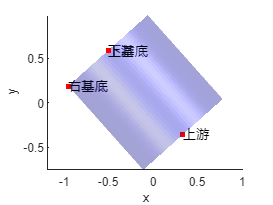

x1 = Bottom_round_center1(1);
y1 = Bottom_round_center1(2);
z1 = Bottom_round_center1(3);
x2 = Bottom_round_center2(1);
y2 = Bottom_round_center2(2);
z2 = Bottom_round_center2(3);


% 计算圆柱底面的基底向量，其中第一个基底向量在竖直面内且朝上
% 输入：
%   x1, y1, z1: 圆柱底面圆心
%   x2, y2, z2: 圆柱顶面圆心
% 输出：
%   u, v: 底面的两个正交基向量，其中 u 在竖直平面内

% 计算轴向向量并归一化
d = [x2 - x1, y2 - y1, z2 - z1];
d = d / norm(d);

% 选择竖直平面内的向量 e
if abs(d(1)) > abs(d(2))  % 如果轴向向量大致沿 X 轴
e = [0, 1, 0];  % 选择 y 方向的单位向量
else  % 否则，如果轴向向量大致沿 Y 轴
e = [1, 0, 0];  % 选择 x 方向的单位向量
end

% 计算第一个基向量 u，使其位于竖直面内
u = cross(d, e);  % 计算与 d 和 e 正交的向量
u = u / norm(u);  % 归一化


% 确保 u 的方向朝上
if u(3) <= 0
u = -u;  % 如果 u 的方向与轴方向相反，反转 u
end

% 计算第二个基向量 v，使其与 d 和 u 正交
v = cross(d, u);  % 计算第二个正交向量
v = -v / norm(v);  % 归一化



UP = Bottom_round_center2+u.*Mradial;
Rig = Bottom_round_center2+v.*Mradial; 

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

scatter3(Bottom_round_center1(1),Bottom_round_center1(2),Bottom_round_center1(3),20,'filled','red')
text(Bottom_round_center1(1),Bottom_round_center1(2),Bottom_round_center1(3),'上游')


scatter3(Bottom_round_center2(1),Bottom_round_center2(2),Bottom_round_center2(3),20,'filled','red')
text(Bottom_round_center2(1),Bottom_round_center2(2),Bottom_round_center2(3),'下游')

scatter3(UP(1),UP(2),UP(3),20,'filled','red')
text(UP(1),UP(2),UP(3),'上基底')

scatter3(Rig(1),Rig(2),Rig(3),20,'filled','red')
text(Rig(1),Rig(2),Rig(3),'右基底')



% t = Bottom_round_center2+u.*Mradial*sin(3*pi./2)+v.*Mradial.*cos(3*pi./2);
% scatter3(t(1),t(2),t(3),20,'filled','b')
% text(t(1),t(2),t(3),'t')


## 4、计算角度

numShengLu = 4;
phi = pi/2-0.001;

toff = zeros(1,2*numShengLu);
roff = zeros(1,2*numShengLu);

Ang = -ShengLuJiaoJiSuan(numShengLu);

% 角度处理
Angt = Ang(1:numShengLu);
AngR = [Angt,pi-Angt(end:-1:1)];

% 角度偏移

rAng = roff(1:numShengLu)./Mradial;
roffAng = [rAng,-rAng(end:-1:1)];

AngR = AngR + roffAng;

## 5、生成圆周点


YuanZhouDian = zeros(3,numShengLu*2);
for i = 1:2*numShengLu
    YuanZhouDian(:,i) = (Bottom_round_center2+u.*Mradial*sin(AngR(i))+v.*Mradial.*cos(AngR(i)))';
end




% scatter3(YuanZhouDian(1,1),YuanZhouDian(2,1),YuanZhouDian(3,1),20,'filled','black')
% text(YuanZhouDian(1,1),YuanZhouDian(2,1),YuanZhouDian(3,1),'圆周1')
% 
% scatter3(YuanZhouDian(1,2),YuanZhouDian(2,2),YuanZhouDian(3,2),20,'filled','black')
% text(YuanZhouDian(1,2),YuanZhouDian(2,2),YuanZhouDian(3,2),'圆周2')
% 
% scatter3(YuanZhouDian(1,3),YuanZhouDian(2,3),YuanZhouDian(3,3),20,'filled','black')
% text(YuanZhouDian(1,3),YuanZhouDian(2,3),YuanZhouDian(3,3),'圆周3')
% 
% scatter3(YuanZhouDian(1,4),YuanZhouDian(2,4),YuanZhouDian(3,4),20,'filled','black')
% text(YuanZhouDian(1,4),YuanZhouDian(2,4),YuanZhouDian(3,4),'圆周4')
% 
% scatter3(YuanZhouDian(1,5),YuanZhouDian(2,5),YuanZhouDian(3,5),20,'filled','black')
% text(YuanZhouDian(1,5),YuanZhouDian(2,5),YuanZhouDian(3,5),'圆周5')
% 
% scatter3(YuanZhouDian(1,6),YuanZhouDian(2,6),YuanZhouDian(3,6),20,'filled','black')
% text(YuanZhouDian(1,6),YuanZhouDian(2,6),YuanZhouDian(3,6),'圆周6')
% 
% scatter3(YuanZhouDian(1,7),YuanZhouDian(2,7),YuanZhouDian(3,7),20,'filled','black')
% text(YuanZhouDian(1,7),YuanZhouDian(2,7),YuanZhouDian(3,7),'圆周7')
% 
% scatter3(YuanZhouDian(1,8),YuanZhouDian(2,8),YuanZhouDian(3,8),20,'filled','black')
% text(YuanZhouDian(1,8),YuanZhouDian(2,8),YuanZhouDian(3,8),'圆周8')


## 6、计算轴向移动

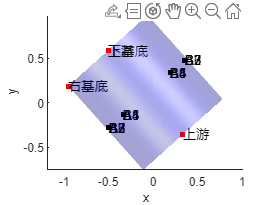

% 总体移动
[xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(PAB,Bottom_round_center1,Bottom_round_center2);
ztyd = sqrt((zN1-Bottom_round_center2(3)).^2+(yN1-Bottom_round_center2(2)).^2+(xN1-Bottom_round_center2(1)).^2);

% phi角移动
PhiDian = zeros(3,numShengLu*2);
disPhiDian = zeros(1,numShengLu*2);

for i = 1:2*numShengLu
    PhiDian(:,i) = v.*Mradial.*cos(AngR(i));
    if i <= numShengLu
        disPhiDian(i) = -sqrt((PhiDian(1,i)).^2+(PhiDian(2,i)).^2+(PhiDian(3,i)).^2).*cos(phi);
    else
        disPhiDian(i) = sqrt((PhiDian(1,i)).^2+(PhiDian(2,i)).^2+(PhiDian(3,i)).^2)*cos(phi);
    end
end


% 偏移移动

PYYD = [toff(1:numShengLu),-toff(numShengLu:-1:1)];


PYallA = ztyd+disPhiDian+PYYD;
PointA = zeros(3,numShengLu*2);
for i = 1:2*numShengLu
    PointA(:,i) = YuanZhouDian(:,i) - d'.*PYallA(i);
end


PYallB = ztyd-disPhiDian;
PointB = zeros(3,numShengLu*2);
for i = 1:2*numShengLu
    PointB(:,i) = YuanZhouDian(:,i) - d'.*PYallB(i);
end
PointB = PointB(:,end:-1:1);


scatter3(PointA(1,1),PointA(2,1),PointA(3,1),20,'filled','green')
text(PointA(1,1),PointA(2,1),PointA(3,1),'A1')
scatter3(PointA(1,2),PointA(2,2),PointA(3,2),20,'filled','green')
text(PointA(1,2),PointA(2,2),PointA(3,2),'A2')
scatter3(PointA(1,3),PointA(2,3),PointA(3,3),20,'filled','green')
text(PointA(1,3),PointA(2,3),PointA(3,3),'A3')
scatter3(PointA(1,4),PointA(2,4),PointA(3,4),20,'filled','green')
text(PointA(1,4),PointA(2,4),PointA(3,4),'A4')
scatter3(PointA(1,5),PointA(2,5),PointA(3,5),20,'filled','green')
text(PointA(1,5),PointA(2,5),PointA(3,5),'A5')
scatter3(PointA(1,6),PointA(2,6),PointA(3,6),20,'filled','green')
text(PointA(1,6),PointA(2,6),PointA(3,6),'A6')
scatter3(PointA(1,7),PointA(2,7),PointA(3,7),20,'filled','green')
text(PointA(1,7),PointA(2,7),PointA(3,7),'A7')
scatter3(PointA(1,8),PointA(2,8),PointA(3,8),20,'filled','green')
text(PointA(1,8),PointA(2,8),PointA(3,8),'A8')


scatter3(PointB(1,1),PointB(2,1),PointB(3,1),20,'filled','black')
text(PointB(1,1),PointB(2,1),PointB(3,1),'B1')
scatter3(PointB(1,2),PointB(2,2),PointB(3,2),20,'filled','black')
text(PointB(1,2),PointB(2,2),PointB(3,2),'B2')
scatter3(PointB(1,3),PointB(2,3),PointB(3,3),20,'filled','black')
text(PointB(1,3),PointB(2,3),PointB(3,3),'B3')
scatter3(PointB(1,4),PointB(2,4),PointB(3,4),20,'filled','black')
text(PointB(1,4),PointB(2,4),PointB(3,4),'B4')
scatter3(PointB(1,5),PointB(2,5),PointB(3,5),20,'filled','black')
text(PointB(1,5),PointB(2,5),PointB(3,5),'B5')
scatter3(PointB(1,6),PointB(2,6),PointB(3,6),20,'filled','black')
text(PointB(1,6),PointB(2,6),PointB(3,6),'B6')
scatter3(PointB(1,7),PointB(2,7),PointB(3,7),20,'filled','black')
text(PointB(1,7),PointB(2,7),PointB(3,7),'B7')
scatter3(PointB(1,8),PointB(2,8),PointB(3,8),20,'filled','black')
text(PointB(1,8),PointB(2,8),PointB(3,8),'B8')